Yao Gahounzo

Individual acticity 11

clear
clc
clear

data = load('ifk.mat');
%addpath('/Users/mathuser/Documents/PHD/Spring_2022/Inverse Theory/regu')

d = data.d;
sigma = 5e-5;

m = size(d,1);
dx = 1/m;

J = 1:20;
x = (J-1/2)*dx;

y = x;
% m function

m_fun = @(alpha,G,d,L) (G'*G + alpha^2*(L'*L))\(G'*d);

% Form G matrix
G = dx*x.*exp(-x.*y');


2. Use the discrepancy principle and the regularized discrepancy principle to find values for $\alpha$ in both first and second order Tikhonov regularization.  

Find the values for $\alpha$ in the first order Tikhonov regularization

- The discrepancy $||\mathbf{Gm_\alpha -d}||_2^2 \leq \delta$.

% The first order Tikhonov regularization

D1 = diag(ones(m-1,1),1);
L1 = -eye(m-1,m) + D1(1:m-1,:);

[U1,V1,X1,Lam1,M1]=gsvd(G,L1);

% The value for delta is 
delta = m*sigma^2;
fun = @(alpha) f_alpha(G,alpha,d,delta,L1);

options = optimset('TolFun',1e-10,'Display','none');
options.TolX = 1e-10;
alpha0 = 2.5058e-5;

alpha1 = fsolve(fun,alpha0,options)

alpha1 = 2.5058e-05

- The regularized discrepancy $||\mathbf{Gm_\alpha -d}||_2^2/ \sigma^2 + \alpha^2||\mathbf{L_1m}_\alpha||_2^2 \leq \delta_{reg}$.


delta_reg = rank(L1)

delta_reg = 19

  
fun2 = @(alpha) freg(G,alpha,d,delta_reg,sigma,L1);

options = optimset('TolFun',1e-10,'Display','none');
options.TolX = 1e-10;

alpha2 = fsolve(fun2,alpha0,options)

alpha2 = 0.0025

Find the values for $\alpha$ in the second order Tikhonov regularization

- The discrepancy $||\mathbf{Gm_\alpha -d}||_2^2 \leq \delta$.

% The second order Tikhonov regularization

D2 = -2*diag(ones(m-1,1),1) + diag(ones(m-2,1),2);
L2 = eye(m-2,m) + D2(1:m-2,:);

[U2,V2,X2,Lam2,M2]=gsvd(G,L2);

fun = @(alpha) f_alpha(G,alpha,d,delta,L2);

options = optimset('Display','none');
%options.TolX = 1e-10;
alpha0 = 2.5058e-5;

alpha3 = fsolve(fun,alpha0,options)

alpha3 = 2.5058e-05

- The regularized discrepancy $||\mathbf{Gm_\alpha -d}||_2^2/ \sigma^2 + \alpha^2||\mathbf{L_2m}_\alpha||_2^2 \leq \delta_{reg}$.


delta_reg = rank(L2)

delta_reg = 18

  
fun3 = @(alpha) freg(G,alpha,d,delta_reg,sigma,L2);

% options = optimset('TolFun',1e-10,'Display','none');
% options.TolX = 1e-10;

alpha4 = fsolve(fun3,alpha0,options)

alpha4 = 0.0148

3. Plot model parameter estimates using first and second order Tikhonov regularization, using values for α from either the discrepancy principle or from the regularized discrepancy principle.

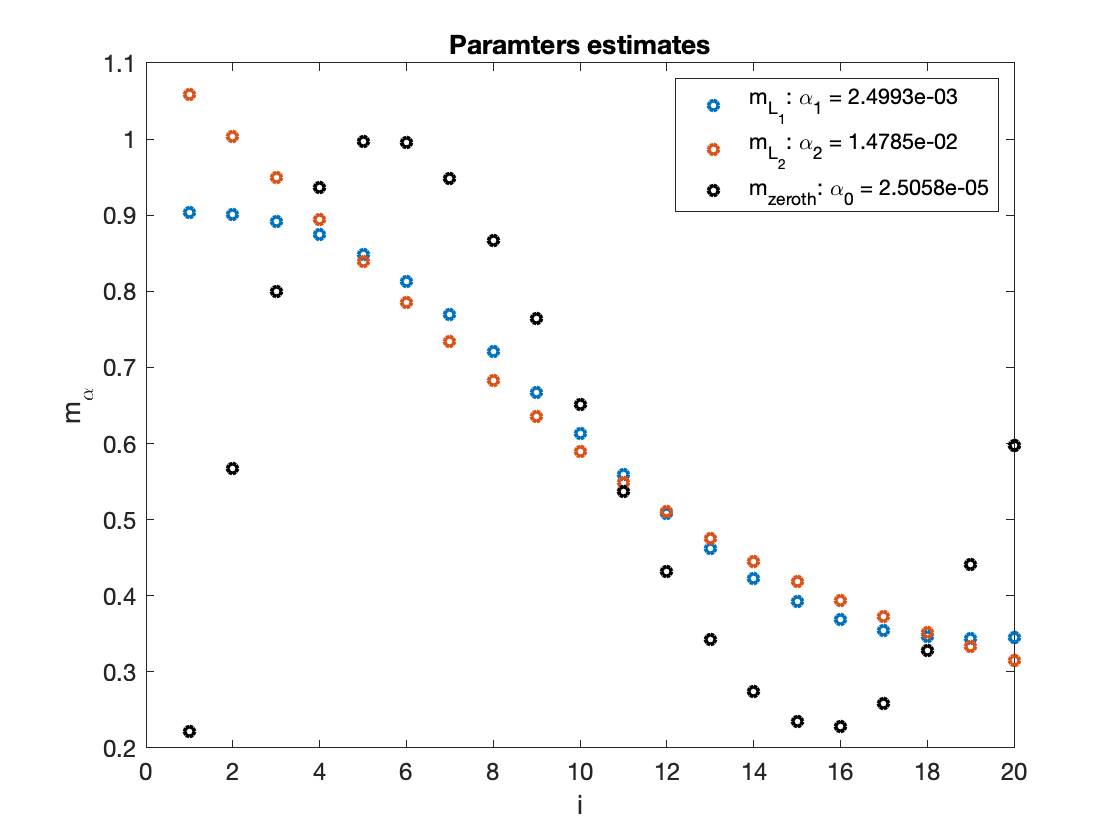

% paramter estimates for zeroth order Tikhonov regularization
m0 = m_fun(alpha0,G,d,eye(m));

alpha = [alpha2,alpha4];

%Plot of the parameter estimates
figure(2)

for i = 1:2
    
    if i == 1
        L = L1; j = 1;
    else 
        L = L2; j = 2;
    end
    
    m_alpha = m_fun(alpha(i),G,d,L);
    
    plot(m_alpha,'o','LineWidth',2,"MarkerSize",5)
    legendInfo{i} = [sprintf('m_{L_{%d}}: \\alpha_{%d} = %.4e',j,i,alpha(i))]; 
    hold on

end

plot(m0,'ko','LineWidth',2,"MarkerSize",5)
legendInfo{3} = [sprintf('m_{zeroth}: \\alpha_{%d} = %.4e',0,alpha0)]; 

h_gc = gca;
h_gc.FontSize = 12;
xlabel('i')
ylabel('m_{\alpha}'); 
legend(legendInfo)
title('Paramters estimates')
hold off

4. Plot the Picard ratios for first and second order Tikhonov regularization for one of the same values of $\alpha$ you used in 3.

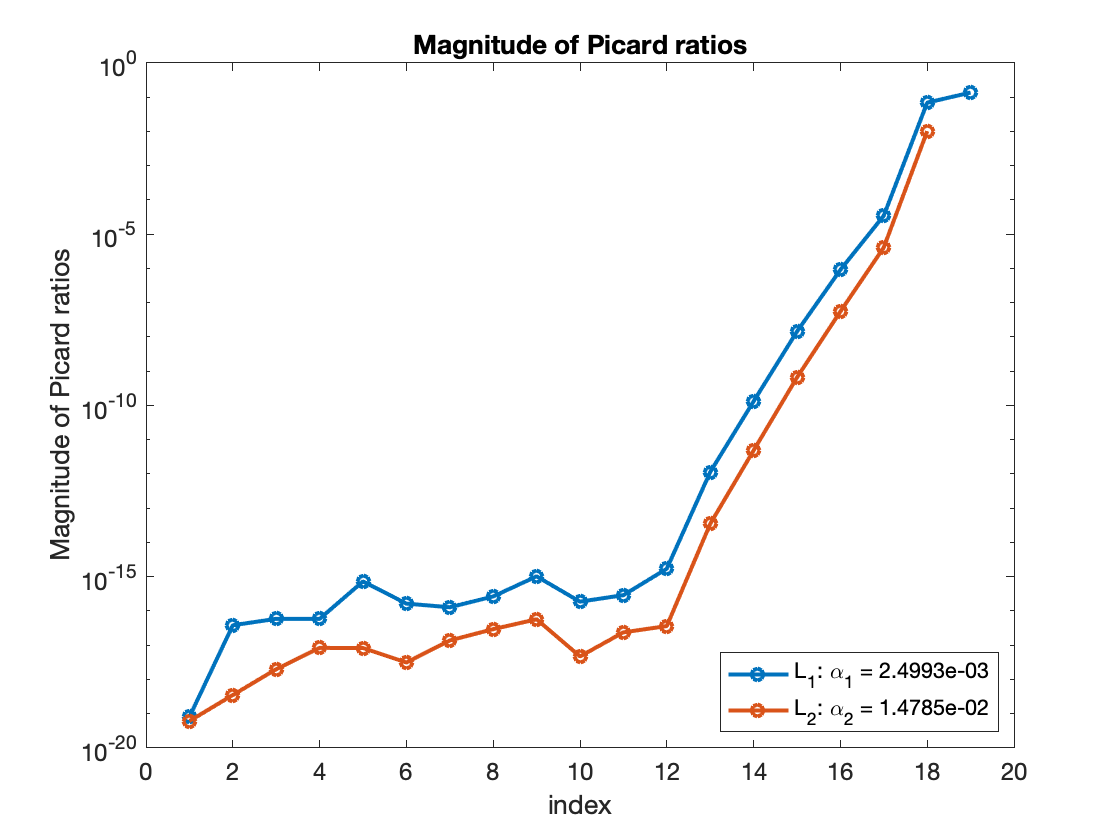

figure(5)

for i = 1:2
    
    if i == 1
        j = 1;
        U = U1;
        s = diag(sqrt(Lam1'*Lam1));
        gamma = s./diag(sqrt(M1'*M1));
        
    else 
        j = 2;
        U = U2;
        s = diag(sqrt(Lam2'*Lam2));
        gamma = s./diag(sqrt(M2'*M2));
    end
    
    f = gamma.^2./(gamma.^2+alpha(i)^2);
    
    Picard = abs(f.*(U'*d./s));     % the magnitude of the Picard ratios
    
    semilogy(1:20,Picard,'o-',"LineWidth",2)
    legendInfo1{i} = [sprintf('L_{%d}: \\alpha_{%d} = %.4e',j,i,alpha(i))]; 
    hold on
        
end

h_gc = gca;
h_gc.FontSize = 12;
legend(legendInfo1,'Location','southeast')
xlabel('index');
ylabel('Magnitude of Picard ratios'); 
title('Magnitude of Picard ratios');

5. Plot model parameter estimates using TGSVD, for both first and second order Tikhonov regularization, with 2 values for q in each case for which you get reasonable model parameter estimates. 

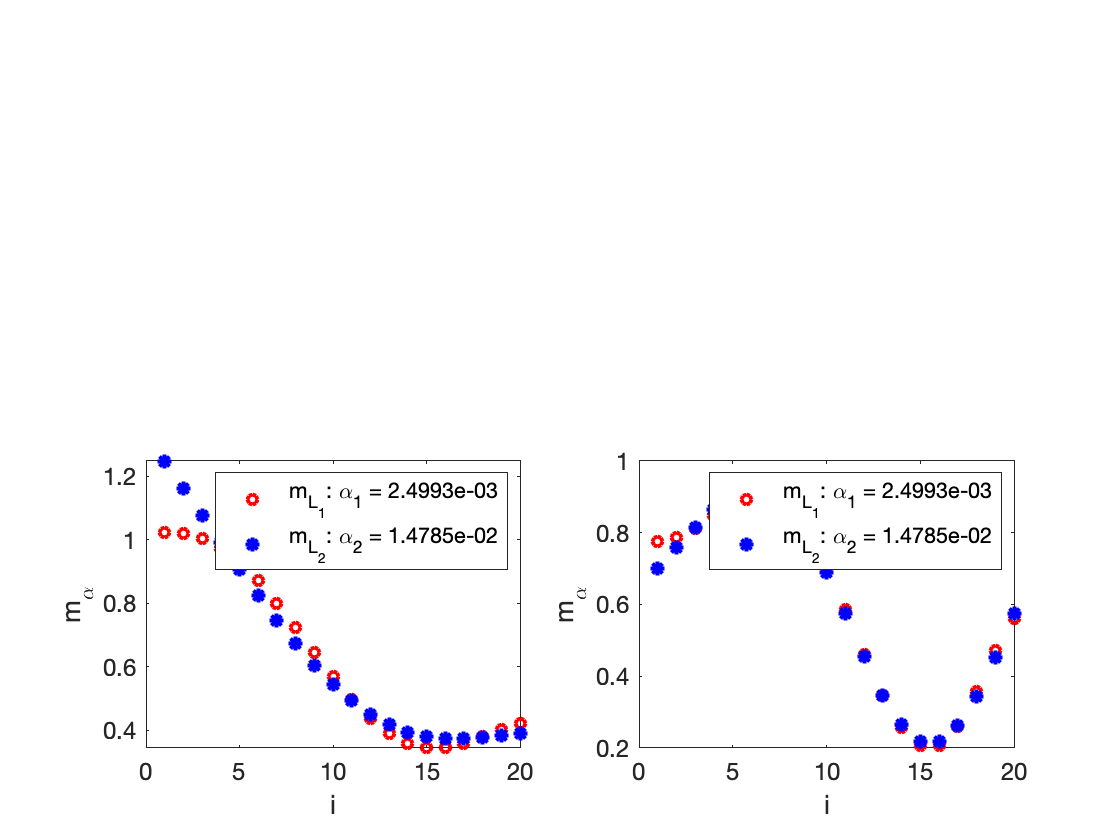

q = [3,4];
n = m;

figure(7)

for q = 3:4
    
    idn = n-q+1:n;
    Y1 = inv(X1)';
    m_qL1 = Y1(:,idn)*(Lam1(idn,idn)\U1(:,idn)'*d); % parameter estimates
    Y2 = inv(X2)';
    m_qL2 = Y2(:,idn)*(Lam2(idn,idn)\U2(:,idn)'*d); % parameter estimates
    
    %Plot of the parameter estimates
    subplot(2,2,q)
    plot(m_qL1,'ro','LineWidth',2,"MarkerSize",5)
    hold on
    plot(m_qL2,'b*','LineWidth',2,"MarkerSize",5)
    
    h_gc = gca;
    h_gc.FontSize = 12;
    xlabel('i')
    ylabel('m_{\alpha}'); 
    
    legend(sprintf('m_{L_{%d}}: \\alpha_1 = %.4e',1,alpha(1)), sprintf('m_{L_{%d}}: \\alpha_2 = %.4e',2,alpha(2)))
    %title('Paramters estimates using TGSVD')
    %hold off
    
end

function res = f_alpha(G,alpha,d,delta,L)

    m_a = (G'*G + alpha^2.*(L'*L))\(G'*d);
    res = (G*m_a-d)'*(G*m_a-d) - delta;
end

function res = freg(G,alpha,d,delta_reg,sigma,L)

    m_a = (G'*G + alpha^2.*(L'*L))\(G'*d);
    Lm = L*m_a;
    res = (G*m_a-d)'*(G*m_a-d)/sigma^2 + alpha^2*(Lm'*Lm) - delta_reg;
end

